%(32°F − 32) × 5/9 = 0°C
AirTemp= (table2array(StoneHarborMet(:,5))-32)*5/9;
Time=datetime(xlsread("ExcelTime.xlsx",'A1:A2871'),'convertfrom','excel');



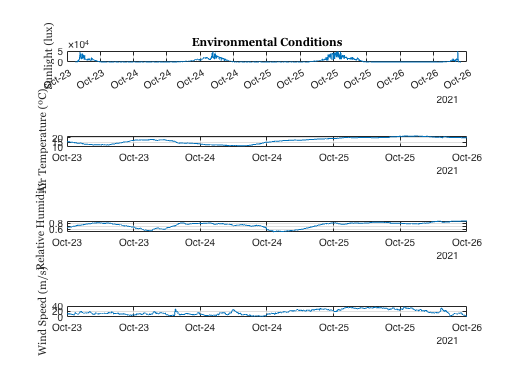

%NOT FINISHED
%sunlight, wind, RH, temp air
figure
subplot(4,1,1) 
plot(hobo.DateTimeEST,hobo.light_lux,'-') 
hold on
ylabel('Sunlight (lux)','FontName','Georgia') 
title('Environmental Conditions','FontName','Georgia')
%title('Sunlight') 
%xlim([datetime(2021,10,22,00,00,00) datetime(2021,10,28,00,00,00)])
%ylim([14 20]) % sets y limit, lower limit then upper limit 
datetick('x','Keeplimits')
xtickformat('MMM-dd')
grid on

subplot(4,1,2) 
plot(Time,AirTemp,'-')
hold on 
ylabel('Air Temperature (ºC)','FontName','Georgia') 
title({'';''})
%title('Air Temperature') 
xlim([datetime(2021,10,23,00,00,00) datetime(2021,10,26,00,00,00)])
%ylim([14 20]) % sets y limit, lower limit then upper limit 
%datetick('x','Keeplimits')
xtickformat('MMM-dd')
grid on

subplot(4,1,3) 
plot(Time,RH,'-')
hold on 
ylabel('Relative Humidity','FontName','Georgia') 
title({'';''})
%title('Relative Humidity') 
xlim([datetime(2021,10,23,00,00,00) datetime(2021,10,26,00,00,00)])
%ylim([6]) % sets y limit, lower limit then upper limit 
%datetick('x','Keeplimits') 
xtickformat('MMM-dd')
grid on

subplot(4,1,4) 
plot(Time,WindSpeed,'-')
hold on 
ylabel('Wind Speed (m/s)','FontName','Georgia') 
title({'';''})
%title('Wind Speed') 
xtickformat('MMM-dd')
xlim([datetime(2021,10,23,00,00,00) datetime(2021,10,26,00,00,00)])
%ylim([6]) % sets y limit, lower limit then upper limit 
%datetick('x','Keeplimits') 
grid on